Capacitance Gauge Data Processing 

Author: Michael Noyce

Description: Program takes raw text files outputed from the CSIR wave tank facility and converts them into .csv files and plots the raw time series and  frequency spectra

Textfile = load("B-2-IRREG_001_csir.txt")

Textfile = 	1.0e+05 *

         0         0    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000
    0.0002    0.0000    0.0000    0.0000
    0.0002    0.0000    0.0000    0.0000


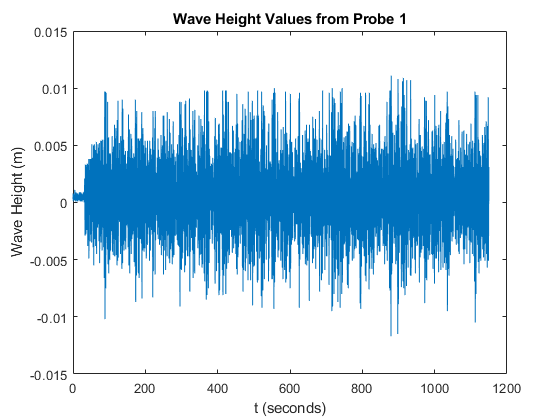

writematrix(Textfile, "B-2-IRREG_001.csv");
CapacitanceData = readtable("B-2-IRREG_001.csv");

Fs = 50; %Guages are sampled at 25Hz or 50 Hz
T = 1/Fs;

timeStamp = CapacitanceData{:, 2}*10; %Correction (time series off by a factor of 10)
probe1Height = CapacitanceData{:, 3};
probe2Height = CapacitanceData{:, 4};

%Differentaite to get acceleration
probe_1_dV = gradient(probe1Height);
dt = T; 
probe_1_velocity = probe_1_dV/dt;

probe_1_dA = gradient(probe_1_velocity);
dt = T; 
probe_1_acceleration = probe_1_dA/dt;


plot(timeStamp, probe1Height)
title('Wave Height Values from Probe 1')
xlabel('t (seconds)')
ylabel('Wave Height (m)')

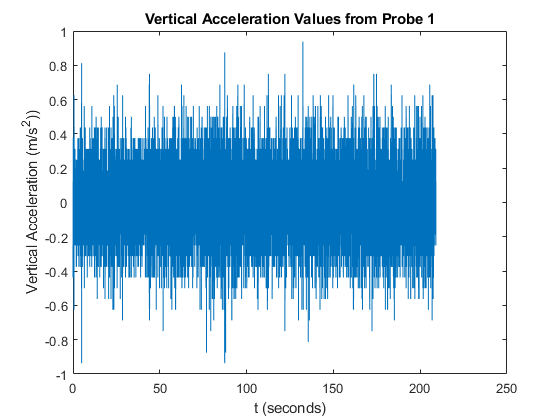


plot(timeStamp(1:10452, 1), probe_1_acceleration(1:10452, 1))
title('Vertical Acceleration Values from Probe 1')
xlabel('t (seconds)')
ylabel('Vertical Acceleration (m/s^2))')

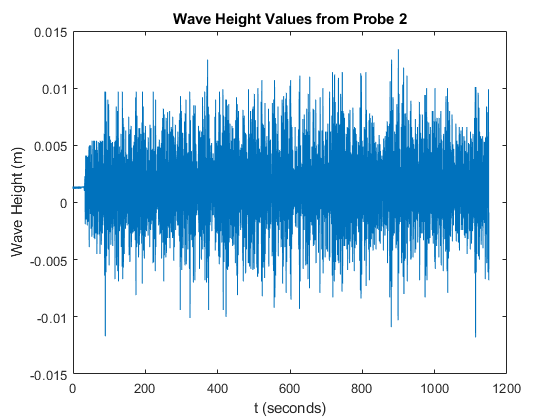


plot(timeStamp, probe2Height)
title('Wave Height Values from Probe 2')
xlabel('t (seconds)')
ylabel('Wave Height (m)')

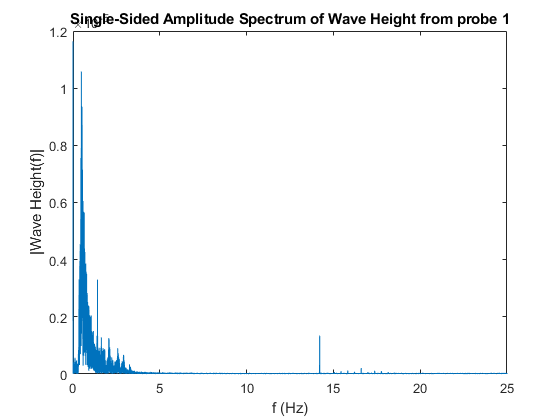


WaveSpectra = fft(probe1Height)*T;
L = length(probe2Height);
P2 = abs(WaveSpectra/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Wave Height from probe 1')
xlabel('f (Hz)')
ylabel('|Wave Height(f)|')

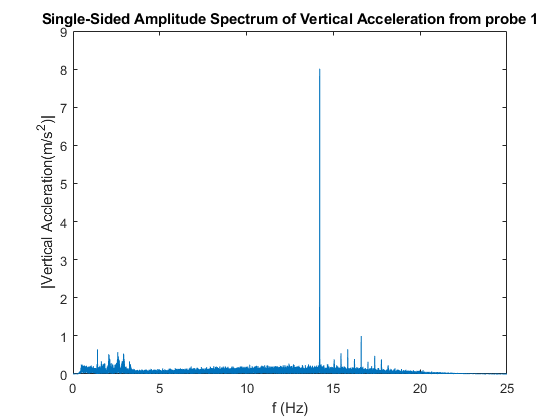


%probe_1_acceleration = lowpass(probe_1_acceleration, 2, Fs);

WaveSpectra = fft(probe_1_acceleration)*Fs;
L = length(probe_1_acceleration);
P2 = abs(WaveSpectra/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Vertical Acceleration from probe 1')
xlabel('f (Hz)')
ylabel('|Vertical Accleration(m/s^2)|')

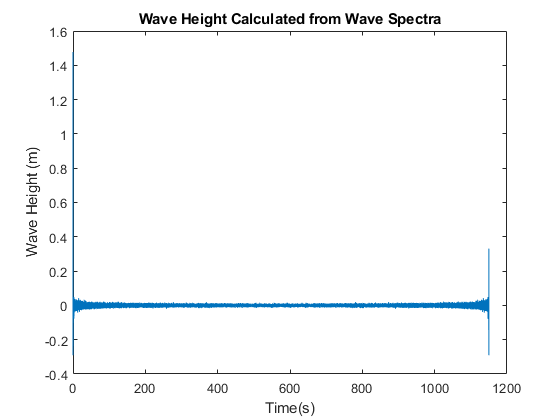



%%Wave Height Calculation
f1 = 0.02; %Lower corner frequency for half cosine taper
f2 = 0.03; %Upper frequency for half cosine taper
fc = 100; %Nyquist Frequency

for i = 1:length(f)
    if f < f1 
        P2(i, 1) = 0;
    end
        if f > f1 & f < f2
            P2(i, 1) = (1/2)*(1-cos(pi*(f-f1)/(f2-f1))*(-1/(2*pi*f^2)))*P2(i, 1);
        end
            if f > f2 & f < fc
                P2(i, 1) = -1/(2*pi*f^2)*P1(i,1); 
            end
end

waveHeight = ifft(P2)*Fs;
t_trunc = (0:length(waveHeight)-1)*T;        % Time vector


plot(t_trunc, waveHeight) 
title('Wave Height Calculated from Wave Spectra')
xlabel('Time(s)')
ylabel('Wave Height (m)')


PSD = pwelch(waveHeight);
L = length(P2);
f = Fs*(0:(L/2))/L;



